Performance specification

- Rise time < 5s

- Overshoot < 10%

- Steadt state error < 2%

M=1000;
B=50;
r=10;
s=tf('s');
P_cruise=1/(M*s+B)

P_cruise =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.



P controller taking value Kp=200

kp=200;
c=pid(kp);
T=feedback(c*P_cruise,1)

T =
 
      200
  ------------
  1000 s + 250
 
Continuous-time transfer function.



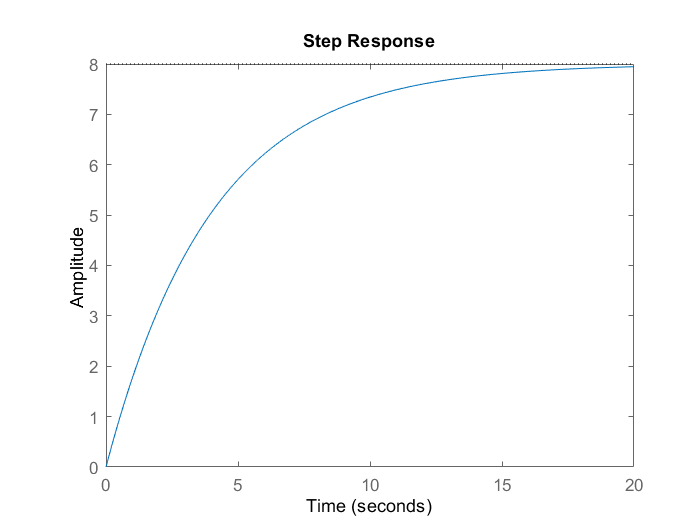

t=0:0.1:20;
step(r*T,t)

As from the graph steady state error is not zero and rise time is very high

selecting Kp=4000

kp=4000;
c=pid(kp);
T=feedback(c*P_cruise,1)

T =
 
      4000
  -------------
  1000 s + 4050
 
Continuous-time transfer function.



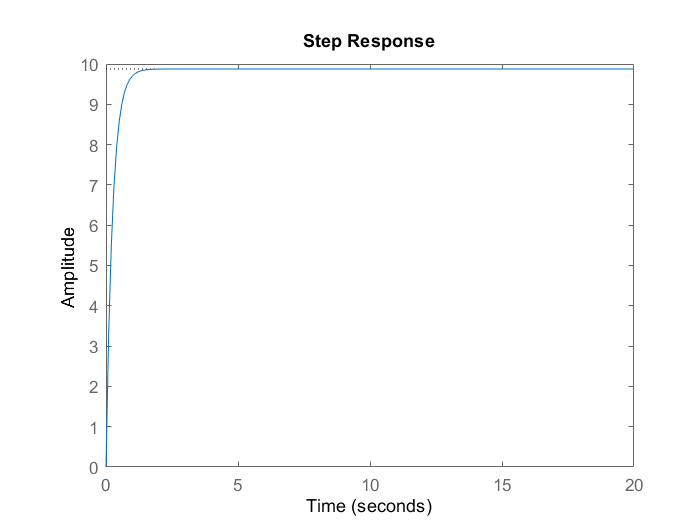

t=0:0.1:20;
step(r*T,t)

As from the graph steady state error is  zero and rise time is very less but this is not practical so lower the proportional gain Kp and and introducing Ki

PI controller

kp=600;
ki=1;
c=pid(kp,ki);
T=feedback(c*P_cruise,1)

T =
 
       600 s + 1
  --------------------
  1000 s^2 + 650 s + 1
 
Continuous-time transfer function.



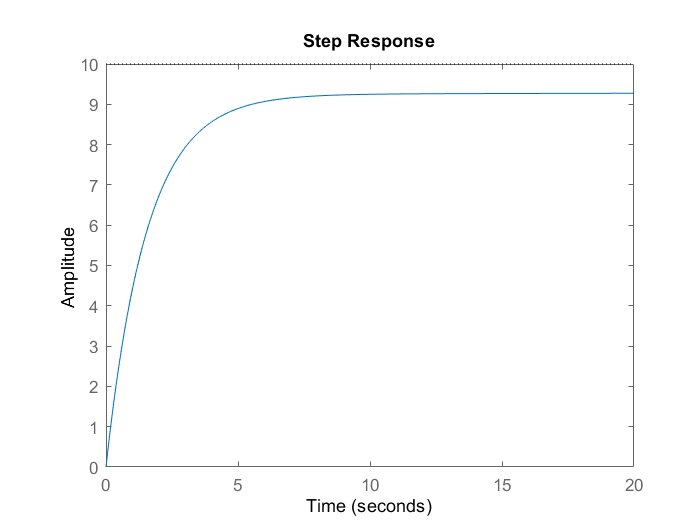

t=0:0.1:20;
step(r*T,t)

We have to adjust kp and ki

kp=700;
ki=30;
c=pid(kp,ki);
T=feedback(c*P_cruise,1)

T =
 
       700 s + 30
  ---------------------
  1000 s^2 + 750 s + 30
 
Continuous-time transfer function.



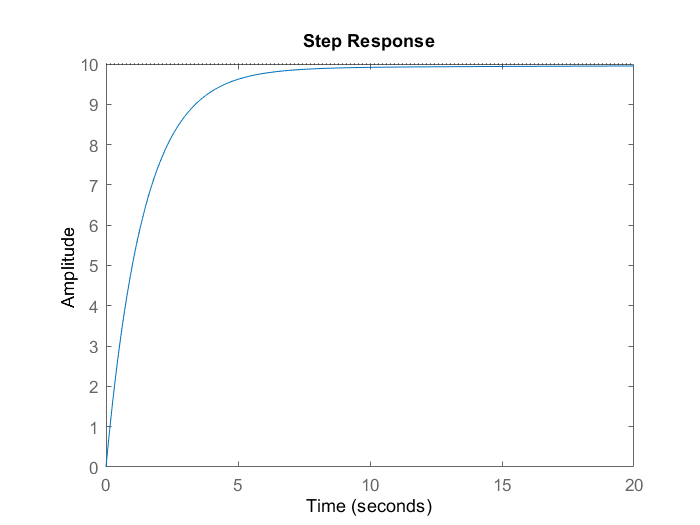

t=0:0.1:20;
step(r*T,t)

As steady state error is zero 

stepinfo(T)

ans = struct with fields:
        RiseTime: 3.2343
    SettlingTime: 6.3246
     SettlingMin: 0.9040
     SettlingMax: 0.9962
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9962
        PeakTime: 25.9674


No requirement of Kd as overshoot is 0